# **Strongly nonlinear dynamic demonstration of adaptiveAnalyze**

The same nonlinear oscillator is solved three ways:

  1. Fine reference:      Newton, dt = 0.001 s

  2. Ordinary coarse:     Newton, dt = 0.020 s

  3. Adaptive coarse:     ModifiedNewton, dt = 0.020 s

The adaptive and ordinary coarse analyses should closely agree because they use the same outer time step. Both may differ from the fine reference because convergence recovery does not control time-integration accuracy.

adaptiveAnalyze always completes the current outer target before starting the next one. If a 0.02 s step is subdivided, the accepted substeps must still add up to exactly 0.02 s.

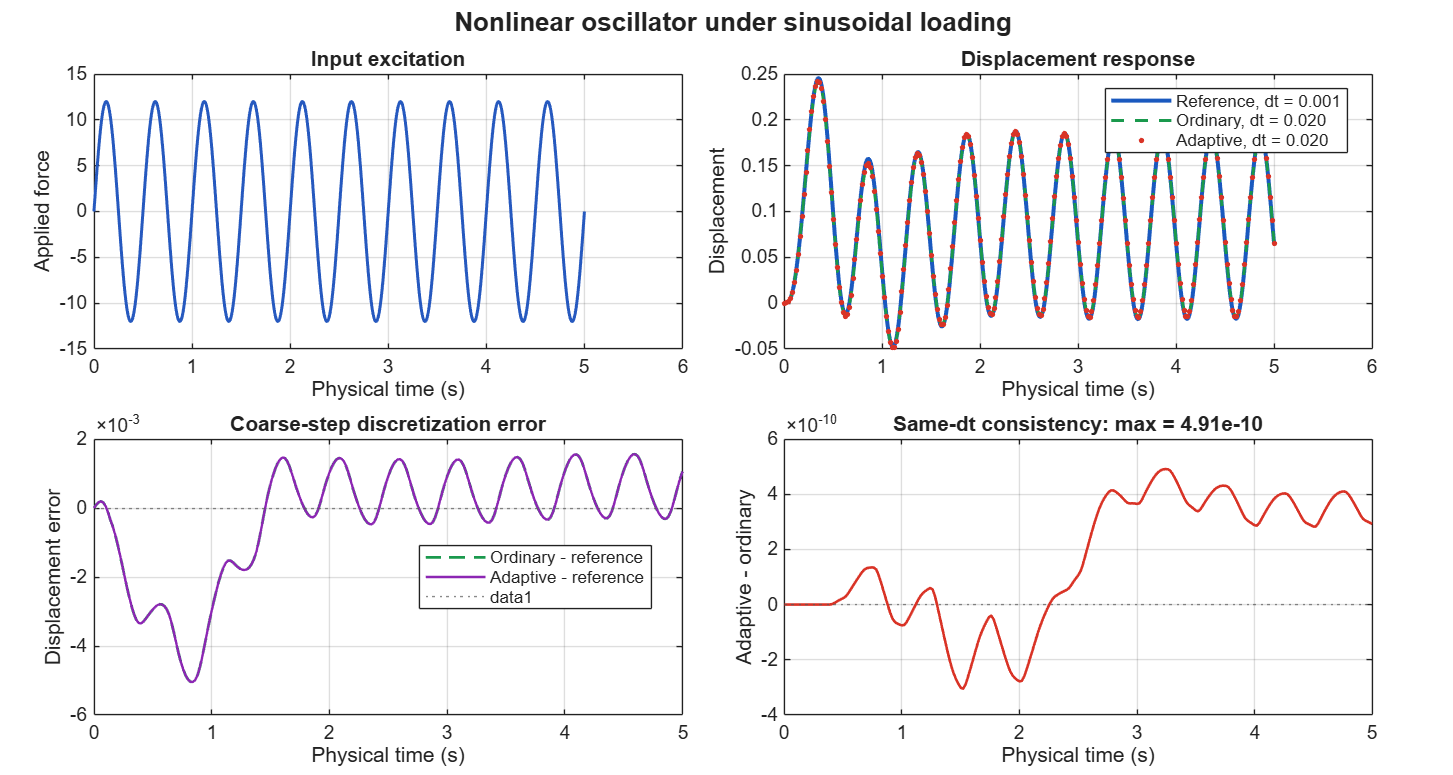

clear;
clc;
close all;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### Parameters

p.mass = 1.0;
p.Fy = 5.0;
p.E0 = 100.0;
p.b = 0.01;
p.R0 = 18.0;
p.cR1 = 0.925;
p.cR2 = 0.15;
p.massDamping = 0.02;

p.forceAmplitude = 12.0;
p.forcePeriod = 0.5;
p.duration = 5.0;

referenceDt = 0.001;
coarseDt = 0.020;

adaptiveResponseFile = string(tempname) + '_adaptive_response.txt';
adaptiveLogFile = string(tempname) + '_adaptive_log.csv';

cleanupFiles = onCleanup(@() deleteFiles( ...
    adaptiveResponseFile, adaptiveLogFile)); %#ok<NASGU>


### Fine-step Newton reference

fprintf('\nRunning the fine-step Newton reference analysis...\n');


Running the fine-step Newton reference analysis...


[referenceTime, referenceDisp] = runFixedAnalysis( ...
    ops, p, referenceDt, 'Newton', 1.0e-12, 30);


### Ordinary coarse-step Newton analysis

fprintf('Running the ordinary coarse-step Newton analysis...\n');

Running the ordinary coarse-step Newton analysis...



[ordinaryTime, ordinaryDisp] = runFixedAnalysis( ...
    ops, p, coarseDt, 'Newton', 1.0e-12, 30);


### Adaptive coarse-step analysis

fprintf('Running the adaptive coarse-step analysis...\n');

Running the adaptive coarse-step analysis...



buildModel(ops, p);
configureAnalysis(ops, 'ModifiedNewton', 1.0e-8, 3);

% Record every accepted adaptive step. Accepted internal substeps also
% appear here if a failed outer step must be subdivided.
ops.recorder( ...
    'Node', ...
    '-file', adaptiveResponseFile, ...
    '-precision', 16, ...
    '-time', ...
    '-node', 2, ...
    '-dof', 1, ...
    'disp');

coarseSteps = round(p.duration / coarseDt);

adaptiveCode = ops.adaptiveAnalyze( ...
    coarseSteps, coarseDt, ...
    '-algorithms', 'KrylovNewton', 'Newton', ...
    '-subdivision', 0.5, 1.0e-5, 10, ...
    '-limits', 1000, ...
    '-log', adaptiveLogFile);

[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 3 iterations  current Norm: 2.47943e-07 (max: 1e-08, Norm deltaR: 1.80575e-05)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] DirectIntegrationAnalysis::analyze() - the Algorithm failed at time 0.14
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 3 iterations  current Norm: 1.79418e-07 (max: 1e-08, Norm deltaR: 1.08206e-10)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] DirectIntegrationAnalysis::analyze() - the Algorithm failed at time 0.14
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 3 iterations  current Norm: 1.08116e-07 (max: 1e-08, Norm deltaR: 2.79329e-06)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] DirectIntegrationAnalysis::analyze() - the Algorit


if adaptiveCode ~= 0
    error('Adaptive analysis failed at t = %.8f with code %d.', ...
        ops.getTime(), adaptiveCode);
end

% Close the recorder before reading its file.
ops.remove('recorders');

adaptiveData = readmatrix(adaptiveResponseFile);

if isempty(adaptiveData) || size(adaptiveData, 2) < 2
    error('The adaptive displacement recorder produced invalid data.');
end

% The recorder starts after the first accepted step, so add the initial
% zero state explicitly.
adaptiveTime = [0.0; adaptiveData(:, 1)];
adaptiveDisp = [0.0; adaptiveData(:, 2)];


### Recovery statistics

attemptLog = readtable(adaptiveLogFile);

% Recovery-stage identifiers:
%   0 = original configuration
%   1 = increased iteration limit
%   2 = fallback algorithm
%   3 = subdivision event
%   4 = fallback convergence test
originalAttempts = nnz(attemptLog.stageID == 0);
algorithmAttempts = nnz(attemptLog.stageID == 2);
algorithmSuccesses = nnz( ...
    attemptLog.stageID == 2 & attemptLog.successFlag == 1);
subdivisions = nnz(attemptLog.stageID == 3);

fprintf('\nAdaptive recovery summary\n');


Adaptive recovery summary


fprintf('  Original attempts:           %d\n', originalAttempts);

  Original attempts:           250


fprintf('  Fallback algorithm attempts: %d\n', algorithmAttempts);

  Fallback algorithm attempts: 162


fprintf('  Fallback algorithm successes:%d\n', algorithmSuccesses);

  Fallback algorithm successes:104


fprintf('  Subdivision events:          %d\n', subdivisions);

  Subdivision events:          0


### Compare results at identical physical times

% The adaptive output may contain internal substep times. Interpolate both
% comparison solutions at exactly those times.
referenceAtAdaptive = interp1( ...
    referenceTime, referenceDisp, adaptiveTime, 'linear');

ordinaryAtAdaptive = interp1( ...
    ordinaryTime, ordinaryDisp, adaptiveTime, 'linear');

adaptiveReferenceError = adaptiveDisp - referenceAtAdaptive;
ordinaryReferenceError = ordinaryAtAdaptive - referenceAtAdaptive;
adaptiveOrdinaryError = adaptiveDisp - ordinaryAtAdaptive;

maxAdaptiveReferenceError = max(abs(adaptiveReferenceError));
maxOrdinaryReferenceError = max(abs(ordinaryReferenceError));
maxAdaptiveOrdinaryError = max(abs(adaptiveOrdinaryError));

rmsAdaptiveReferenceError = ...
    sqrt(mean(adaptiveReferenceError.^2));

rmsAdaptiveOrdinaryError = ...
    sqrt(mean(adaptiveOrdinaryError.^2));

referencePeak = max(abs(referenceDisp));
ordinaryPeak = max(abs(ordinaryDisp));
adaptivePeak = max(abs(adaptiveDisp));


### Stored regression values

% These values were obtained using Newton, Newmark average acceleration,
% dt = 0.001 s, tolerance = 1e-12, and 30 maximum iterations.
expectedReferencePeak = 0.245473151640312;
expectedReferenceFinal = 0.064566975576412;

fprintf('\nResponse comparison\n');


Response comparison


fprintf('  Reference peak displacement:      %.12f\n', referencePeak);

  Reference peak displacement:      0.245473151640


fprintf('  Ordinary coarse peak displacement:%.12f\n', ordinaryPeak);

  Ordinary coarse peak displacement:0.241856742875


fprintf('  Adaptive peak displacement:       %.12f\n', adaptivePeak);

  Adaptive peak displacement:       0.241856742875


fprintf('  Reference final displacement:     %.12f\n', referenceDisp(end));

  Reference final displacement:     0.064566975576


fprintf('  Ordinary final displacement:      %.12f\n', ordinaryDisp(end));

  Ordinary final displacement:      0.065628363721


fprintf('  Adaptive final displacement:      %.12f\n', adaptiveDisp(end));

  Adaptive final displacement:      0.065628364013



fprintf('\nError comparison\n');


Error comparison


fprintf('  Adaptive versus reference, max:   %.6e\n', ...
    maxAdaptiveReferenceError);

  Adaptive versus reference, max:   5.043399e-03


fprintf('  Ordinary versus reference, max:   %.6e\n', ...
    maxOrdinaryReferenceError);

  Ordinary versus reference, max:   5.043399e-03


fprintf('  Adaptive versus ordinary, max:    %.6e\n', ...
    maxAdaptiveOrdinaryError);

  Adaptive versus ordinary, max:    4.911170e-10


fprintf('  Adaptive versus reference, RMS:   %.6e\n', ...
    rmsAdaptiveReferenceError);

  Adaptive versus reference, RMS:   1.680388e-03


fprintf('  Adaptive versus ordinary, RMS:    %.6e\n', ...
    rmsAdaptiveOrdinaryError);

  Adaptive versus ordinary, RMS:    2.768587e-10


### Verification

% Every analysis must reach the complete requested physical time.
assert(abs(referenceTime(end) - p.duration) < 1.0e-10, ...
    'The reference analysis did not reach the final time.');

assert(abs(ordinaryTime(end) - p.duration) < 1.0e-10, ...
    'The ordinary analysis did not reach the final time.');

assert(abs(adaptiveTime(end) - p.duration) < 1.0e-10, ...
    'The adaptive analysis did not reach the final time.');

% Check the fine solution against independently stored values.
assert(abs(referencePeak - expectedReferencePeak) < 5.0e-6, ...
    'The fine-step peak does not match the stored reference.');

assert(abs(referenceDisp(end) - expectedReferenceFinal) < 5.0e-6, ...
    'The fine-step final response does not match the stored reference.');

% The important implementation check is adaptive versus ordinary coarse.
% Their common dt = 0.02 discretization should produce nearly equal results.
assert(maxAdaptiveOrdinaryError < 1.0e-5, ...
    'adaptiveAnalyze does not match ordinary analyze at the same dt.');

assert(rmsAdaptiveOrdinaryError < 1.0e-6, ...
    'The adaptive-versus-ordinary RMS error is too large.');

% Confirm that the example actually exercised algorithm switching.
assert(algorithmAttempts > 0, ...
    'No fallback algorithm was attempted.');

assert(algorithmSuccesses > 0, ...
    'No fallback algorithm converged.');

### Applied sinusoidal force

frequency = 1.0 / p.forcePeriod;

referenceForce = p.forceAmplitude * ...
    sin(2.0 * pi * frequency * referenceTime);

adaptiveForce = p.forceAmplitude * ...
    sin(2.0 * pi * frequency * adaptiveTime);

### Plots

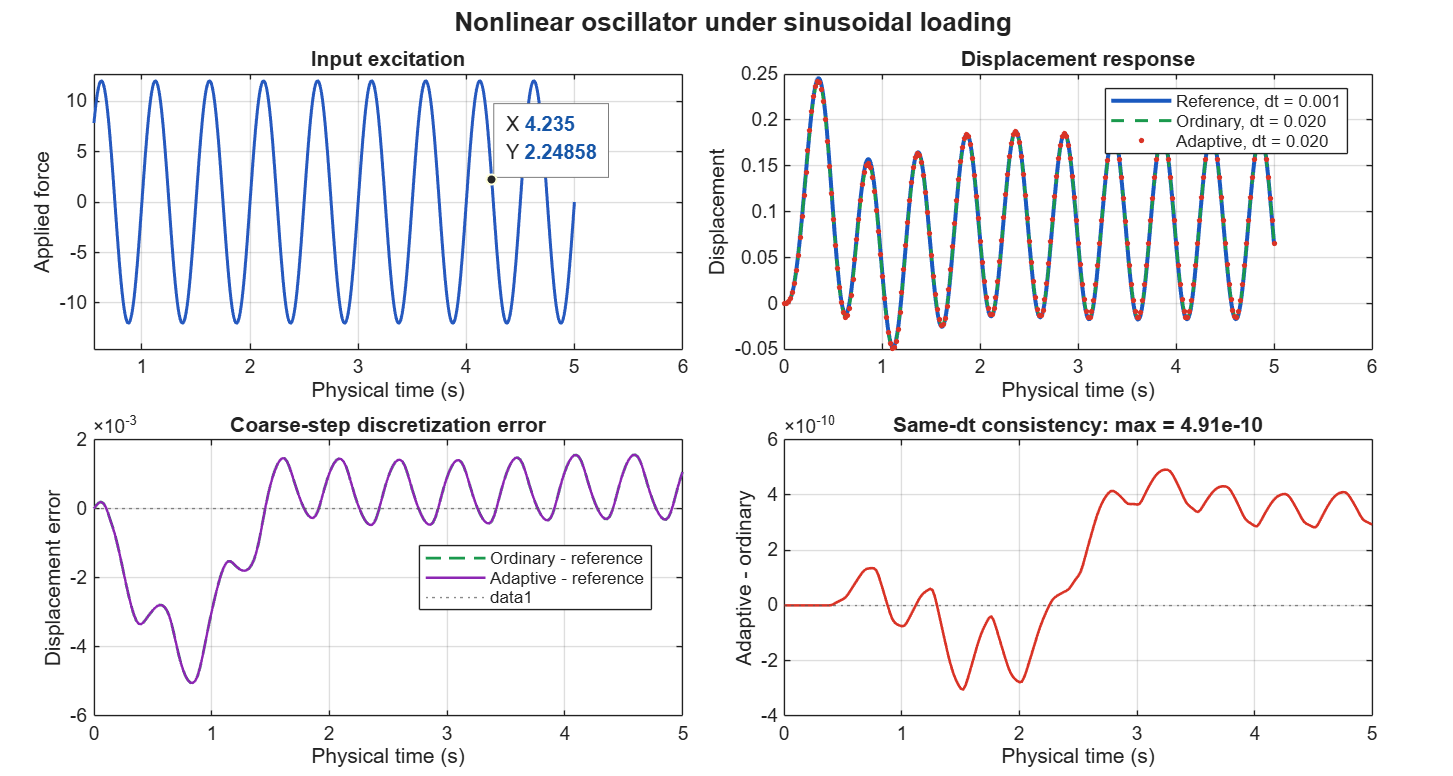

figure( ...
    'Color', 'white', ...
    'Name', 'Nonlinear adaptive dynamic analysis', ...
    'Position', [100 100 1500 800]);

layout = tiledlayout(2, 2, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

title(layout, ...
    'Nonlinear oscillator under sinusoidal loading', ...
    'FontWeight', 'bold');

% Sinusoidal excitation
nexttile;

plot(referenceTime, referenceForce, ...
    'LineWidth', 1.5, ...
    'Color', [0.15, 0.35, 0.75]);

grid on;
box on;
xlabel('Physical time (s)');
ylabel('Applied force');
title('Input excitation');

% Displacement histories
nexttile;

plot(referenceTime, referenceDisp, ...
    '-', ...
    'LineWidth', 2.0, ...
    'Color', [0.10, 0.35, 0.75], ...
    'DisplayName', 'Reference, dt = 0.001');

hold on;

plot(ordinaryTime, ordinaryDisp, ...
    '--', ...
    'LineWidth', 1.5, ...
    'Color', [0.10, 0.60, 0.30], ...
    'DisplayName', 'Ordinary, dt = 0.020');

plot(adaptiveTime, adaptiveDisp, ...
    '.', ...
    'MarkerSize', 8, ...
    'Color', [0.85, 0.20, 0.15], ...
    'DisplayName', 'Adaptive, dt = 0.020');

grid on;
box on;
xlabel('Physical time (s)');
ylabel('Displacement');
title('Displacement response');
legend('Location', 'best');

% Coarse solutions relative to the fine reference
nexttile;

plot(adaptiveTime, ordinaryReferenceError, ...
    '--', ...
    'LineWidth', 1.4, ...
    'Color', [0.10, 0.60, 0.30], ...
    'DisplayName', 'Ordinary - reference');

hold on;

plot(adaptiveTime, adaptiveReferenceError, ...
    '-', ...
    'LineWidth', 1.2, ...
    'Color', [0.55, 0.15, 0.70], ...
    'DisplayName', 'Adaptive - reference');

yline(0.0, ':', 'Color', [0.35, 0.35, 0.35]);

grid on;
box on;
xlabel('Physical time (s)');
ylabel('Displacement error');
title('Coarse-step discretization error');
legend('Location', 'best');

% Adaptive versus ordinary at the same outer time step
nexttile;

plot(adaptiveTime, adaptiveOrdinaryError, ...
    '-', ...
    'LineWidth', 1.3, ...
    'Color', [0.85, 0.20, 0.15]);

yline(0.0, ':', 'Color', [0.35, 0.35, 0.35]);

grid on;
box on;
xlabel('Physical time (s)');
ylabel('Adaptive - ordinary');
title(sprintf('Same-dt consistency: max = %.2e', ...
    maxAdaptiveOrdinaryError));


fprintf('\nAll verification checks passed.\n');


All verification checks passed.


fprintf('adaptiveAnalyze completed every outer time target.\n');

adaptiveAnalyze completed every outer time target.


fprintf('The adaptive and ordinary dt = 0.02 solutions agree.\n');

The adaptive and ordinary dt = 0.02 solutions agree.


fprintf(['Their difference from dt = 0.001 is time-discretization ', ...
    'error, not an incomplete outer step.\n']);

Their difference from dt = 0.001 is time-discretization error, not an incomplete outer step.



ops.wipe();


### Local functions


function [time, displacement] = runFixedAnalysis( ...
    ops, p, dt, algorithm, tolerance, maxIterations)
%RUNFIXEDANALYSIS Run an ordinary fixed-step transient analysis.

buildModel(ops, p);
configureAnalysis(ops, algorithm, tolerance, maxIterations);

numberOfSteps = round(p.duration / dt);

time = zeros(numberOfSteps + 1, 1);
displacement = zeros(numberOfSteps + 1, 1);

for i = 1:numberOfSteps
    code = ops.analyze(1, dt);

    if code ~= 0
        error('Analysis failed at step %d, time %.8f, code %d.', ...
            i, ops.getTime(), code);
    end

    time(i + 1) = ops.getTime();
    displacement(i + 1) = ops.nodeDisp(2, 1);
end
end

function buildModel(ops, p)
%BUILDMODEL Create a nonlinear SDOF oscillator.
%
% The excitation amplitude exceeds the Steel02 yield force, producing
% repeated yielding and nonlinear hysteretic response.

ops.wipe();

ops.model('basic', '-ndm', 1, '-ndf', 1);

ops.node(1, 0.0);
ops.node(2, 0.0);

ops.fix(1, 1);
ops.mass(2, p.mass);

ops.uniaxialMaterial( ...
    'Steel02', 1, ...
    p.Fy, p.E0, p.b, ...
    p.R0, p.cR1, p.cR2);

ops.element( ...
    'zeroLength', 1, 1, 2, ...
    '-mat', 1, ...
    '-dir', 1);

% The Trig time series applies:
%
%   forceAmplitude * sin(2*pi*time/forcePeriod)
ops.timeSeries( ...
    'Trig', 1, ...
    0.0, p.duration, p.forcePeriod, ...
    '-factor', p.forceAmplitude);

ops.pattern('Plain', 1, 1);
ops.load(2, 1.0);

% Small mass-proportional damping.
ops.rayleigh(p.massDamping, 0.0, 0.0, 0.0);
end

function configureAnalysis(ops, algorithm, tolerance, maxIterations)
%CONFIGUREANALYSIS Configure average-acceleration Newmark integration.

ops.constraints('Plain');
ops.numberer('Plain');
ops.system('BandGeneral');

ops.test( ...
    'NormDispIncr', ...
    tolerance, ...
    maxIterations, ...
    0);

ops.algorithm(algorithm);
ops.integrator('Newmark', 0.5, 0.25);
ops.analysis('Transient');
end

function deleteFiles(responseFile, logFile)
%DELETEFILES Delete temporary recorder and recovery-log files.

if isfile(responseFile)
    delete(responseFile);
end

if isfile(logFile)
    delete(logFile);
end
end